# Assignment 1

clear
rng(10)
addpath('functions')


## Question 1.1

- A(q−1)=1−3.88098254q−1 −5.64726905q−2+3.6515443q−3−0.88525793q−4.

- B(q−1)=0.4453368−1.7110786q−1+2.49838163q−2−1.64272524q−3+0.41012833q−4B(q^{-1}) = 0.4453368 - 1.7110786 q^{-1} + 2.49838163 q^{-2} - 1.64272524 q^{-3} + 0.41012833 q^{-4}B(q−1)=0.4453368−1.7110786q−1+2.49838163q−2−1.64272524q−3+0.41012833q−4

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];
% q^-1






## Question 1.2

- ϕt�=[yt−1�,yt−2�,yt−3�,yt−4�,ut�,ut−1�,ut−2�,ut−3�,ut−4�]T.

- θ=[3.88098254,5.64726905,−3.6515443,0.88525793,0.4453368,−1.7110786,2.49838163,−1.64272524,0.41012833]T\theta = [3.88098254, 5.64726905, -3.6515443, 0.88525793, 0.4453368, -1.7110786, 2.49838163, -1.64272524, 0.41012833]^Tθ=[3.88098254,5.64726905,−3.6515443,0.88525793,0.4453368,−1.7110786,2.49838163,−1.64272524,0.41012833]T

syms y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4 
phi =  [y_1 y_2 y_3 y_4 u_0 u_1 u_2 u_3 u_4]';
% q^-1
theta = ([3.88098254,5.64726905,-3.6515443,0.88525793,0.4453368,-1.7110786,2.49838163,-1.64272524,0.41012833]');
vpa(phi'*theta)

$$ans = 0.44533679999999997711768173758173\,u_{0}-1.7110786000000000051102233555866\,u_{1}+2.4983816299999999088754520926159\,u_{2}-1.6427252400000000864821458890219\,u_{3}+0.41012832999999998540019419124292\,u_{4}+3.8809825400000002026956735790009\,y_{1}+5.6472690500000002344904714846052\,y_{2}-3.6515442999999998541227341775084\,y_{3}+0.88525792999999997068272250544396\,y_{4}$$

## Question 1.3

Stable with no stochastic term:

eigs = roots(s.A)

eigs =    0.9902 + 0.0000i
   0.9947 + 0.0000i
   0.9480 + 0.0005i
   0.9480 - 0.0005i


abs(eigs)

ans =     0.9902
    0.9947
    0.9480
    0.9480


## Question 1.4

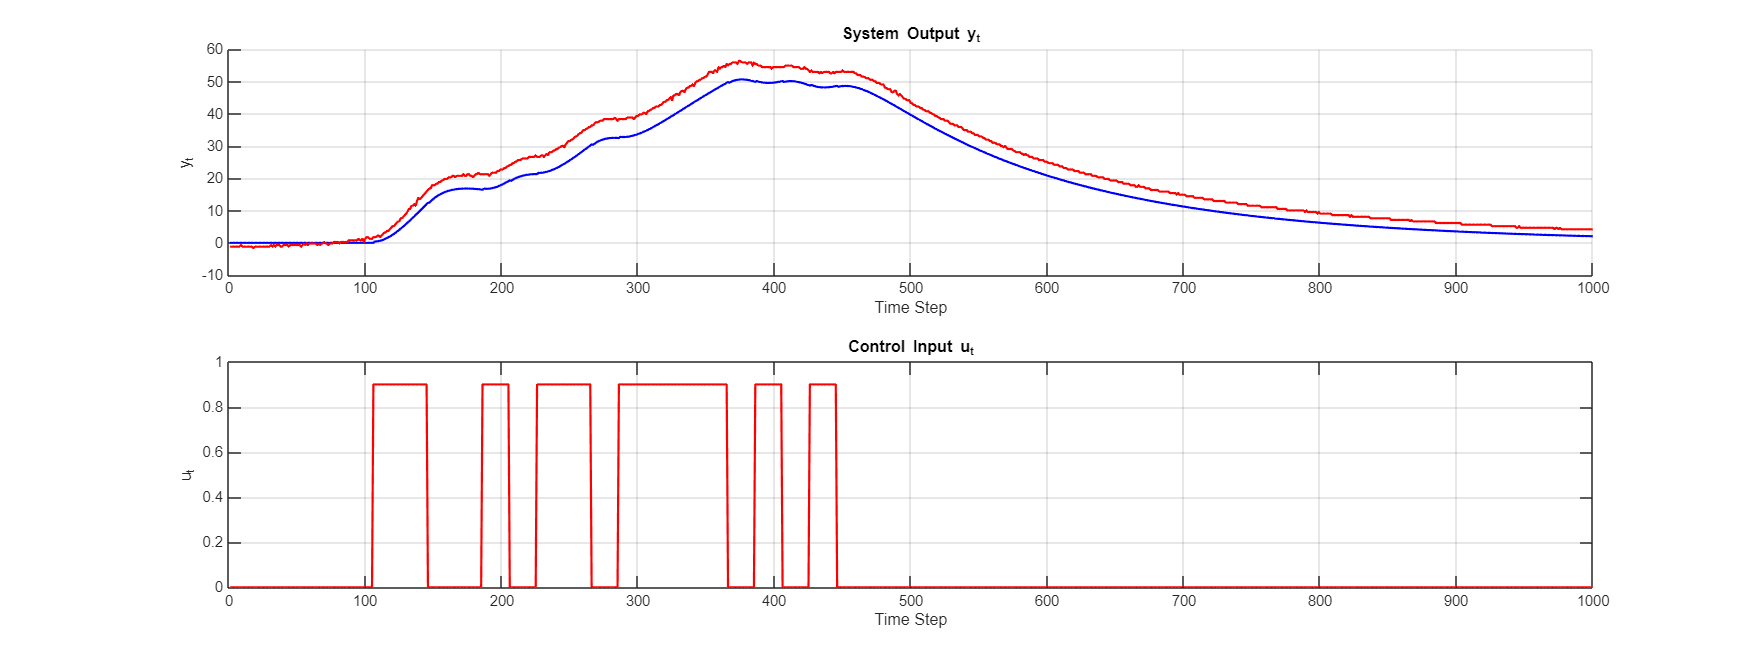

data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 1;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,2);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);
y_temp = s.y;
u_temp = s.u;

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
plot(data(1:s.N,1), 'r', 'LineWidth', 1.5);
hold off

hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.5

m = 100;
s.A = [1	-0.628054600018803	-0.340780053692741	-0.123253583434919	0.0964114956017608];
s.B = [0.154187616014832	-0.156669833035350	0.0706699303652418	0.0359340974766847	0.392677261233270];

[G,S] = diophantine(s.A,1,m)

G =     1.0000    0.6281    0.7352    0.7990    0.7334    0.7630    0.7567    0.7486    0.7514    0.7467    0.7444    0.7424    0.7395    0.7372    0.7348    0.7323    0.7299    0.7274    0.7250    0.7226    0.7202    0.7178    0.7154    0.7130    0.7106    0.7083    0.7059    0.7036    0.7012    0.6989    0.6966    0.6942    0.6919    0.6896    0.6873    0.6850    0.6828    0.6805    0.6782    0.6760    0.6737    0.6715    0.6692    0.6670    0.6648    0.6626    0.6604    0.6582    0.6560    0.6538


S =     0.5515    0.2033    0.0147   -0.0534


R = conv(s.B,G)

R =     0.1542   -0.0598    0.0856    0.0883    0.4551    0.3323    0.3664    0.3909    0.3675    0.3771    0.3749    0.3716    0.3722    0.3702    0.3690    0.3680    0.3666    0.3655    0.3642    0.3630    0.3618    0.3606    0.3594    0.3582    0.3570    0.3558    0.3546    0.3535    0.3523    0.3511    0.3499    0.3488    0.3476    0.3465    0.3453    0.3442    0.3430    0.3419    0.3407    0.3396    0.3385    0.3373    0.3362    0.3351    0.3340    0.3329    0.3318    0.3307    0.3296    0.3285


## Question 1.6

y_obs = data(:,1);  % First row: actual observed outputs
u_data = data(:,2);      % Second row: input values
k = s.k;
N = length(y_obs);  % Total number of observations

% Initialize predicted values
offset = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k;
y_pred = [zeros(1, offset),zeros(1, N)];  % Store predictions
y_sampl =  [zeros(offset,1);y_obs];
u_sampl = [zeros(offset,1);u_data];

% Simulate predictions iteratively
for t = numel(s.B)+max([numel(S),numel(s.B),numel(R)])+k:N-numel(R) + numel(s.B) + offset
    % Predict y_{t+m} using the ARX equation
    % y_pred(t+m) = R* u_data(t+m-k+(0:numel(R)-1)) + S * s.y(t-(0:numel(S)-1));
    Rterm(t) = R* u_sampl(t+m-numel(s.B)-k-(0:numel(R)-1));
    Sterm(t) = S * y_sampl(t-(0:numel(S)-1));
    y_pred(t+m-offset) =  Rterm(t) + Sterm(t);
end
y_pred = y_pred(1:end-1-offset)';

% Compute Mean Absolute Error (MAE)
MAE = mean(abs(y_pred(m+1:end) - s.y(m+1:end)));

% Display result
fprintf('Mean Absolute Error (MAE): %.5f\n', MAE);

Mean Absolute Error (MAE): 4.35701


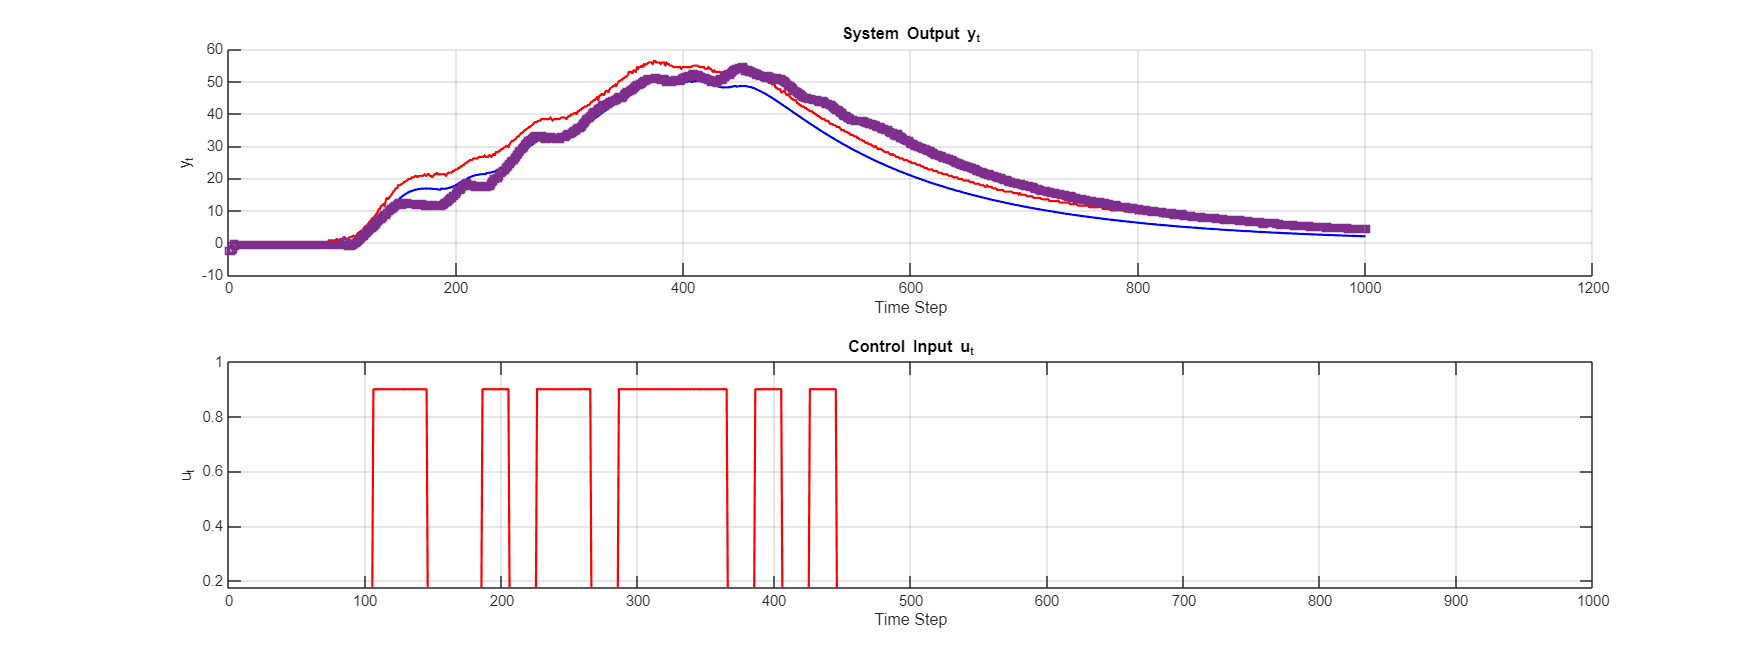


sys = idpoly(s.A,s.B,'nk',1,'InputDelay',max([length(s.A), length(s.B)]));
data_arx = sim(sys,u_data);
figure
yp = predict(sys,[y_obs,u_data],m);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
% plot(data_arx(1:end), 'g--', 'LineWidth', 1.5);
plot(data(1:end-1,1), 'r', 'LineWidth', 1.5);
plot(y_pred, 'g--', 'LineWidth', 1.5);
plot(yp(1:end)', 's', 'LineWidth', 1.5);

hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.7

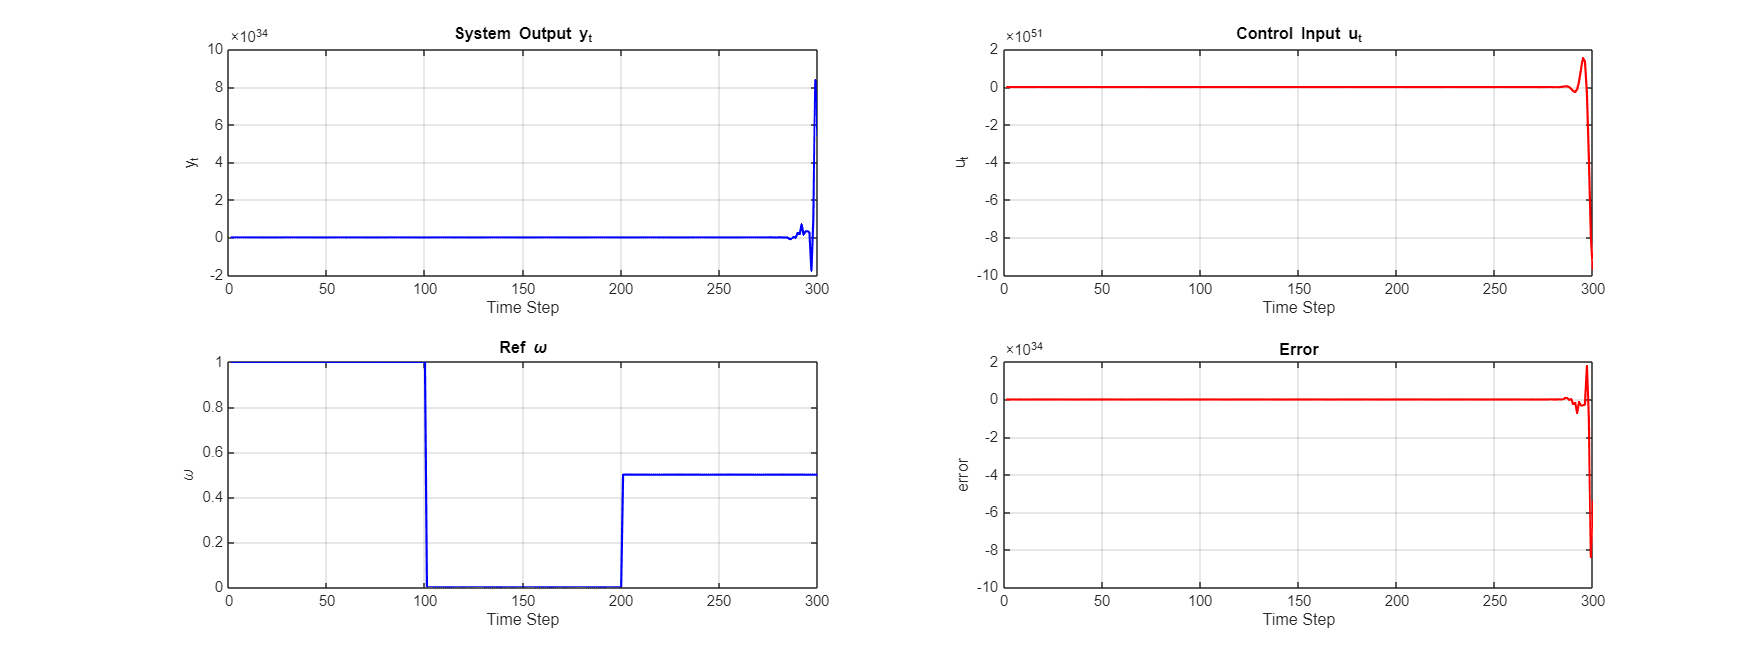

s.u_data = readmatrix('Assignment1_ObservationsAndInputs.txt')';
%% System Parameters
s.N = 300;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
s.k = 1;  % Input delay
s.alpha = 0.5; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref =  [ones(100,1);zeros(100,1);0.5*ones(100,1)]';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], u_data(:,2) [4], Off [5])
SP = 4;
Stochastic = 1;
ctrl = 3;
s = run_case(s, SP, Stochastic, ctrl);

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];

%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,2,1);
plot(s.y, 'b', 'LineWidth', 1.5);
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,2,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;
subplot(2,2,3)
plot(s.omega, 'b', 'LineWidth', 1.5);
title('Ref \omega');
% ylim([-max(omega)*1.2,max(omega)*1.2])
xlabel('Time Step');
ylabel('\omega');
grid on;
subplot(2,2,4)
plot(s.omega-s.y', 'r', 'LineWidth', 1.5);
title('Error');
xlabel('Time Step');
ylabel('error');
grid on;

## Question 1.8

% Construct the regression matrix Phi_t
% y_obs = y_temp;
y_obs = y_obs(1:1000);
u_data = u_temp;
N = length(y_temp);
Phi = zeros(N-max([numel(s.A),numel(s.B)]), 9);
% Y = (max([numel(s.A),numel(s.B)])+1:N);  % Output from t=3 onwards

for t = max([numel(s.A),numel(s.B)])+1:N
    Phi(t, :) = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)];
end

% Phi = zeros(N,numel(s.A)-1+ numel(s.B)-1+1);
% k = find(s.B, 1); % Find the first nonzero index
% 
% for t = max(numel(s.A),numel(s.B)): N
%     Phi(t,:) = [-y_obs(t-(1:numel(s.A)-1))', u_data(t-(k-1:numel(s.B)-1))']; %remember the sign sincee we are moviang y_t-n to right side
% end


% Solve for estimated parameters using least squares
theta_hat = (Phi' * Phi) \ (Phi' * y_obs);
% theta_hat = (Phi' * Phi)^-1 * (Phi' * Y);
% theta_hat = inv(phi'*phi)*phi'*y' 


% Display estimated vs true parameters
disp('Estimated Parameters:');

Estimated Parameters:


A_est = theta_hat(1:4)'

A_est =    -0.6281   -0.3408   -0.1233    0.0964


B_est = theta_hat(5:9)'

B_est =     0.1542   -0.1567    0.0707    0.0359    0.3927


s.A = [1,A_est];
s.B = B_est;

% Compute estimated parameter covariance matrix
sigma_sq_hat = var(y_obs - Phi * theta_hat);  % Residual variance
cov_theta = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covariance

disp('Estimated Variance of Parameters:');

Estimated Variance of Parameters:


% disp(diag(cov_theta));  % Display variance of each parameter

% Compare with theoretical variance
theoretical_variance = s.sigma_e^2 * inv(Phi' * Phi);
disp('Theoretical Variance of Parameters:');

Theoretical Variance of Parameters:


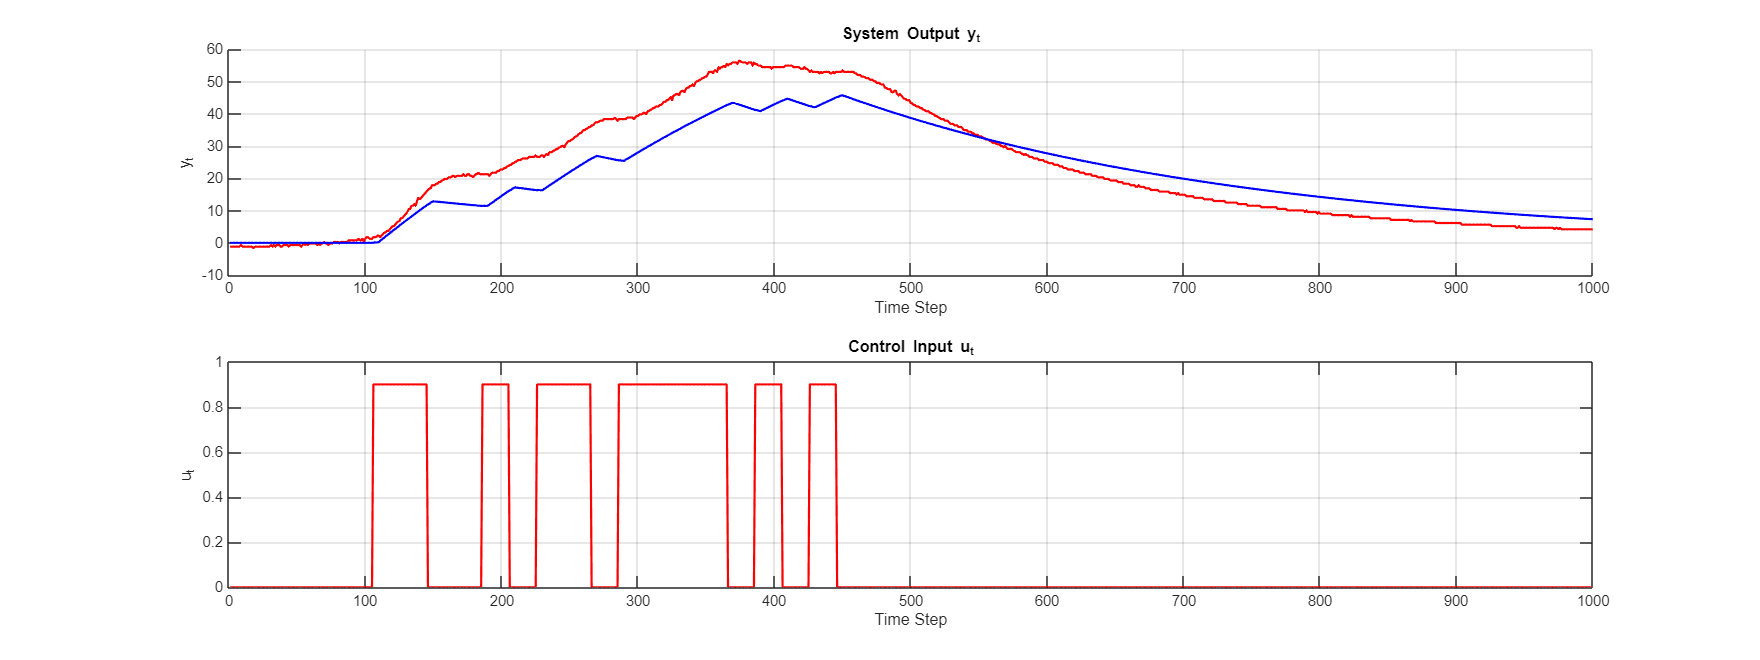

% disp(diag(theoretical_variance));


data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 1;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,2);


% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(y_obs(1:end), 'r', 'LineWidth', 1.5);
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

### PZ cancellation

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];

sys = tf(s.B, s.A,1)


sys =
 
  0.4453 z^4 - 1.711 z^3 + 2.498 z^2 - 1.643 z + 0.4101
  -----------------------------------------------------
     z^4 - 3.881 z^3 + 5.647 z^2 - 3.652 z + 0.8853
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


msys = minreal(sys,0.1)


msys =
 
  0.4453 z^3 - 1.289 z^2 + 1.276 z - 0.4326
  -----------------------------------------
     z^3 - 2.933 z^2 + 2.867 z - 0.9338
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


% pole(sys)
% zero(sys)
% figure
% pzplot(sys);
% pole(msys)
% zero(msys)
% figure
% pzplot(msys);
% s.B = msys.Numerator{1};
% s.A = msys.Denominator{1};


da = iddata(data(:,1), data(:,2), 1)


da =

Time domain data set with 1001 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties


er = {1:5,0:5}

er = 1×2 cell array
    {[1 2 3 4 5]}    {[0 1 2 3 4 5]}


% figure
% plot(da)
z = [data(:,1),data(:,2)];
z = [y_temp,u_temp]

z =          0         0
         0         0
         0         0
         0         0
         0         0
   -0.0000         0
   -0.0000         0
   -0.0000         0
   -0.0000         0
   -0.0000         0


sys = arx(z, [4,5,0]);
L = linearRegressor({'y1','u1'},{1:3,1:3})

L = Linear regressors in variables y1, u1
       Variables: {'y1'  'u1'}
            Lags: {[1 2 3]  [1 2 3]}
     UseAbsolute: [0 0]
    TimeVariable: 't'

  Regressors described by this set

sys = nlarx(da,L,idLinear)


sys =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables y1, u1
  List of all regressors

Output function: Linear with offset
Sample time: 1 seconds

Status:                                          
Estimated using NLARX on time domain data "da".  
Fit to estimation data: 98.36% (prediction focus)
FPE: 0.08833, MSE: 0.08684                       



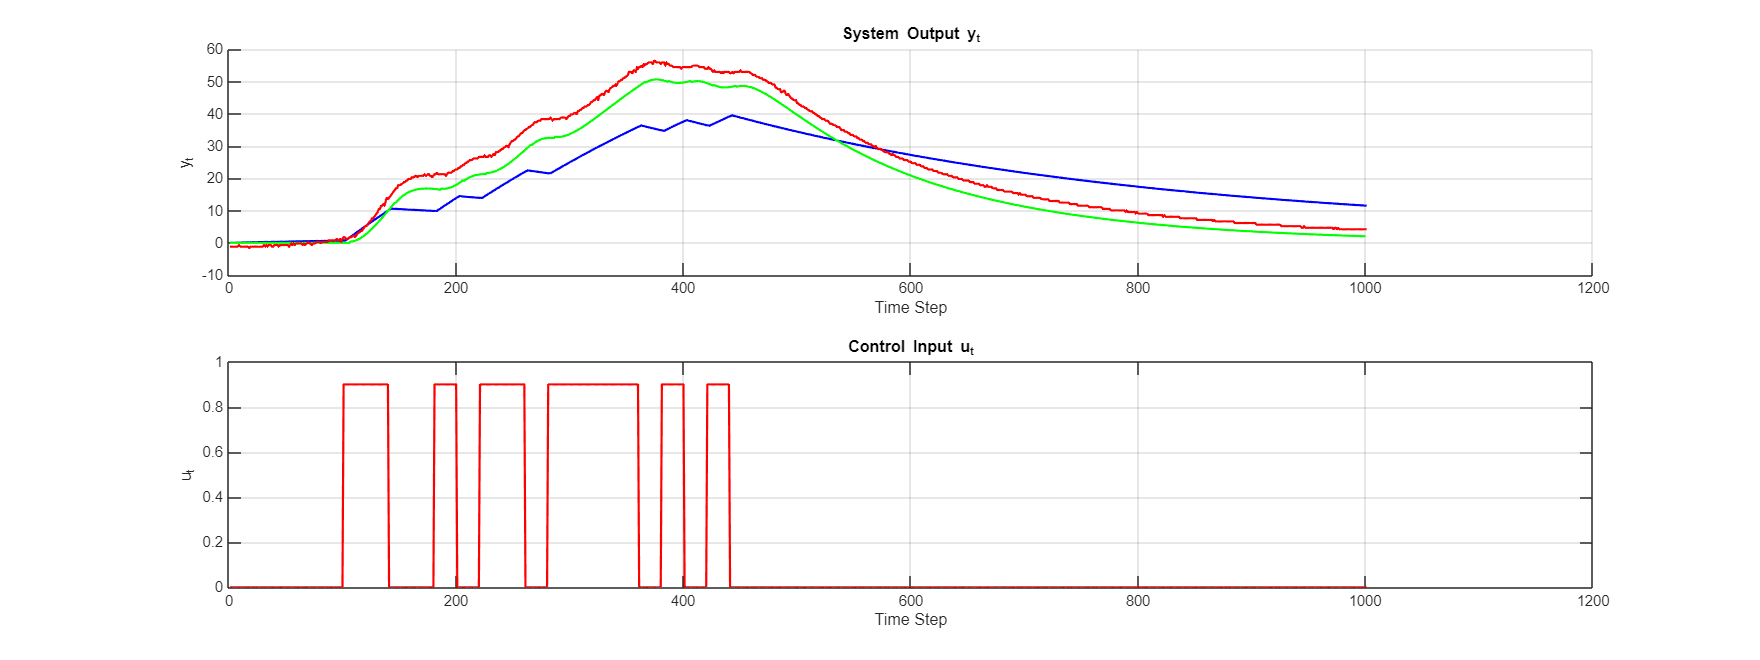

y = sim(sys,data(:,2));


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(y', 'b', 'LineWidth', 1.5);
plot(y_temp', 'g', 'LineWidth', 1.5);
plot(data(:,1), 'r', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(data(:,2), 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;

## Question 1.9

s.A = [1, -3.88098254, 5.64726905, -3.6515443, 0.88525793];
s.B = [0.4453368,-1.71110786,2.49838163, -1.64272524, 0.41012833];
y_obs = y_obs(1:1000);
u_data = u_temp;
num = 9

num = 9

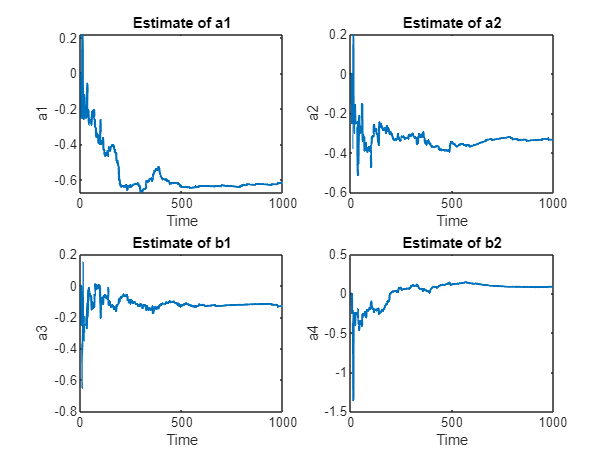

% Initialize Recursive Least Squares (RLS) Parameters
theta_rls = zeros(9, N); % Store estimated parameters over time
P = 100 * eye(9); % Initial covariance (high uncertainty)
lambda = 0.999; % Forgetting factor
theta_hat = zeros(9, 1); % Initial parameter estimates

% Recursive Estimation
for t = max([numel(s.A),numel(s.B)])+1:N
    % Regression vector Phi_t
    % Phi_t = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)];
    Phi_t = [-y_obs(t-1),-y_obs(t-2), -y_obs(t-3),-y_obs(t-4),u_data(t-s.k),u_data(t-1-s.k), u_data(t-2-s.k), u_data(t-3-s.k),u_data(t-4-s.k)]';
    
    % Kalman gain
    K_t = P * Phi_t / (lambda + Phi_t' * P * Phi_t);
    
    % Prediction error
    e_t = y_obs(t) - Phi_t' * theta_hat;
    
    % Parameter update
    theta_hat = theta_hat + K_t * e_t;
    
    % Covariance update
    P = (P - K_t * Phi_t' * P) / lambda;
    
    % Store estimates over time
    theta_rls(:, t) = theta_hat;
end

% Plot parameter evolution
figure;
subplot(2,2,1); plot(theta_rls(1,:), 'LineWidth', 1.5); title('Estimate of a1'); xlabel('Time'); ylabel('a1');
subplot(2,2,2); plot(theta_rls(2,:), 'LineWidth', 1.5); title('Estimate of a2'); xlabel('Time'); ylabel('a2');
subplot(2,2,3); plot(theta_rls(3,:), 'LineWidth', 1.5); title('Estimate of b1'); xlabel('Time'); ylabel('a3');
subplot(2,2,4); plot(theta_rls(4,:), 'LineWidth', 1.5); title('Estimate of b2'); xlabel('Time'); ylabel('a4');


% Display final estimated parameters
disp('Final Estimated Parameters (Recursive LS):');

Final Estimated Parameters (Recursive LS):


disp(theta_hat);

   -0.6171
   -0.3328
   -0.1322
    0.0868
    0.1653
   -0.1681
    0.0729
    0.0342
    0.4128






A_est = theta_hat(1:4)'

A_est =    -0.6171   -0.3328   -0.1322    0.0868


B_est = theta_hat(5:9)'

B_est =     0.1653   -0.1681    0.0729    0.0342    0.4128


s.A = [1,A_est];
s.B = B_est;

% Compute estimated parameter covariance matrix
% sigma_sq_hat = var(y_obs - Phi * theta_hat);  % Residual variance
cov_theta = sigma_sq_hat * inv(Phi' * Phi);  % Theoretical covariance

disp('Estimated Variance of Parameters:');

Estimated Variance of Parameters:


% disp(diag(cov_theta));  % Display variance of each parameter

% Compare with theoretical variance
theoretical_variance = s.sigma_e^2 * inv(Phi' * Phi);
disp('Theoretical Variance of Parameters:');

Theoretical Variance of Parameters:


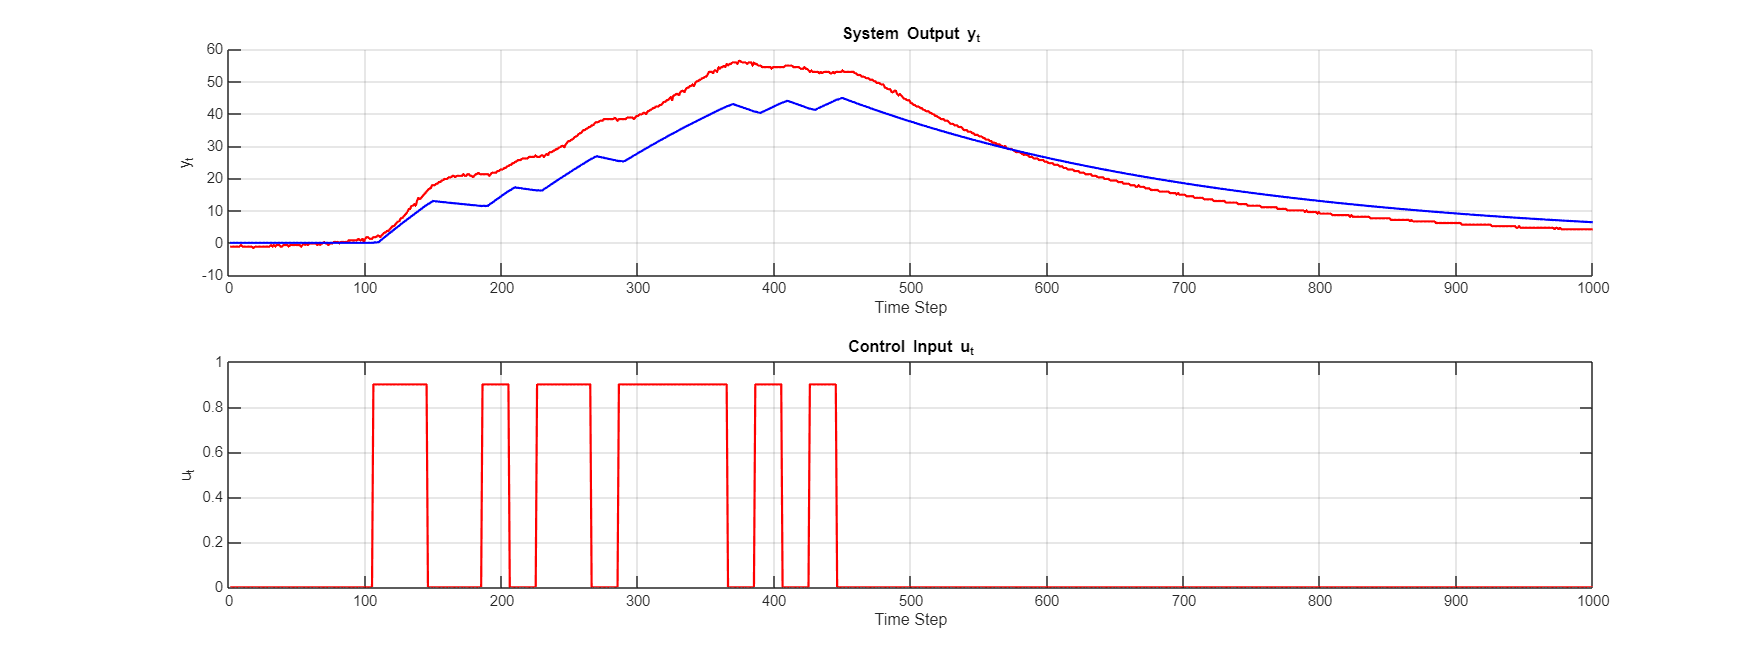

% disp(diag(theoretical_variance));


data = readmatrix('Assignment1_ObservationsAndInputs.txt')';

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
s.u_data = data(:,2);
%% System Parameters
s.N = 1000;  % Number of time steps
s.sigma_e = 10^-10;  % Standard deviation of process noise
% s.sigma_e = 0.00001;
s.k = 1;  % Input delay
s.alpha = 0.01; % Gain for P ctrl
n_max = max([length(s.A),length(s.B)]);
s.u_init = zeros(n_max,1);
s.y_init = zeros(n_max,1);
s.ref = data(1:s.N,2);

% Setpoint(SP) (constant = 0 [1], step change [2] or square wave [3], s.ref [4])
% Stochastic(Stochastic) (True [1],  False [2])
% Control type (ctrl) (Pctrl [1], MV [2], MV0 [3], s.u_data [4], Off [5])
SP = 1;
Stochastic = 1;
ctrl = 4;
s = run_case(s, SP, Stochastic, ctrl);


%% Plot Results
fig = figure();
fig.Position(3:4) = [1600, 600];
subplot(2,1,1);
hold on
plot(y_obs(1:end), 'r', 'LineWidth', 1.5);
plot(s.y(1:end), 'b', 'LineWidth', 1.5);
hold off
title('System Output y_t');
xlabel('Time Step');
ylabel('y_t');
grid on;
subplot(2,1,2);
plot(s.u, 'r', 'LineWidth', 1.5);
title('Control Input u_t');
xlabel('Time Step');
ylabel('u_t');
grid on;